# HW6

## Part 1: Blurring an Image

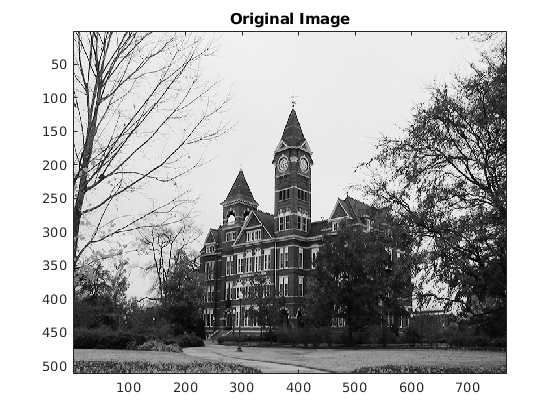

set(0, 'DefaultFigureColormap', gray(256))
% Note: Working with UINT8 images seems to result in quantization error,
% making all inverse filtered images horrible. Switching to double fixes
% the issue.
image = double(rgb2gray(imread('samford.png')));
ker = fspecial('disk', 6);

image_F = fft2(image);
ker_F = fft2(ker, size(image, 1), size(image, 2));
blurred_image = real(ifft2(ker_F .* image_F));
figure(1)
imagesc(image)
title("Original Image")

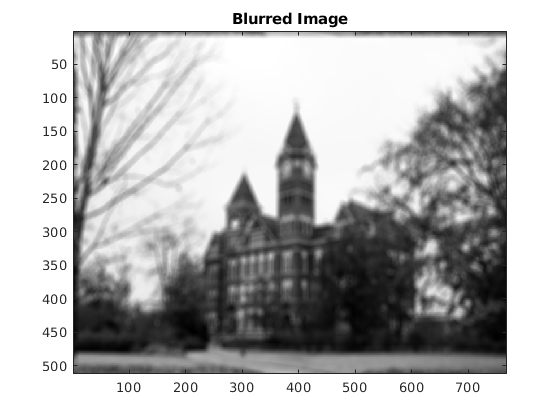

figure(2)
imagesc(blurred_image)
title("Blurred Image")

## Part 2: Inverse Filtering

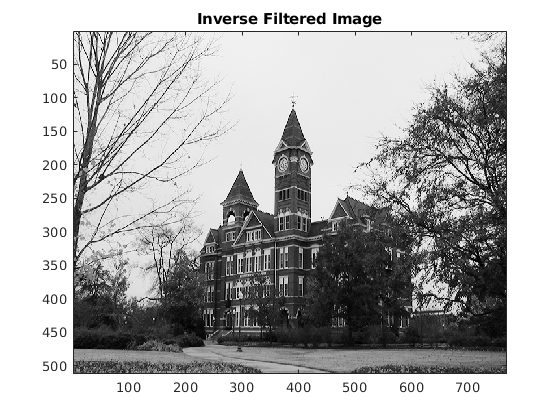

blurred_image_F = fft2(blurred_image);
ker_F = fft2(ker, size(blurred_image, 1), size(blurred_image, 2));

inverse_image = real(ifft2(blurred_image_F ./ ker_F));
figure(3)
imagesc(inverse_image)
title("Inverse Filtered Image");

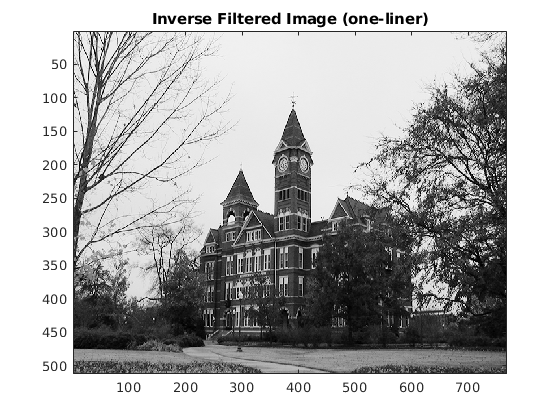


inverse_image_one_line = real(...
    ifft2(...
    fft2(blurred_image) ./ fft2(ker, size(blurred_image, 1), size(blurred_image, 2)))...
    );
figure(4)
imagesc(inverse_image_one_line)
title("Inverse Filtered Image (one-liner)");

## Part 3: Effects of Noise

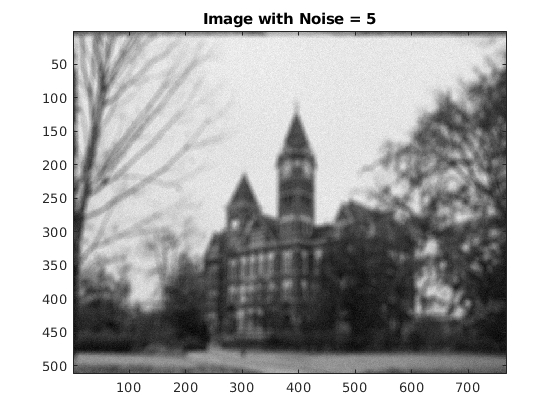

sigma = 5;
noise =  sigma * randn(size(image));
noise_image = blurred_image + noise;
figure(7)
imagesc(noise_image)
title(['Image with Noise = ', num2str(sigma)])

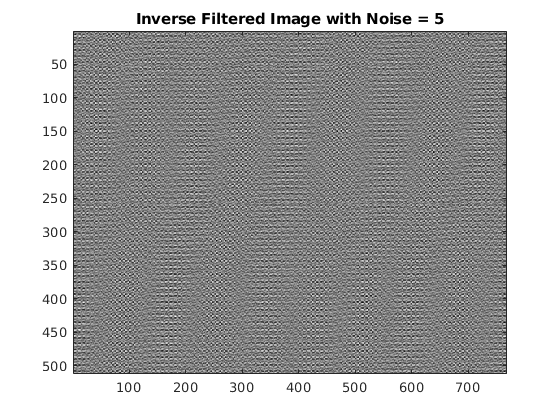


inverse_noise_image = real(...
    ifft2(...
    fft2(noise_image) ./ fft2(ker, size(blurred_image, 1), size(blurred_image, 2)))...
    );
figure(8)
imagesc(inverse_noise_image)
title(['Inverse Filtered Image with Noise = ', num2str(sigma)])

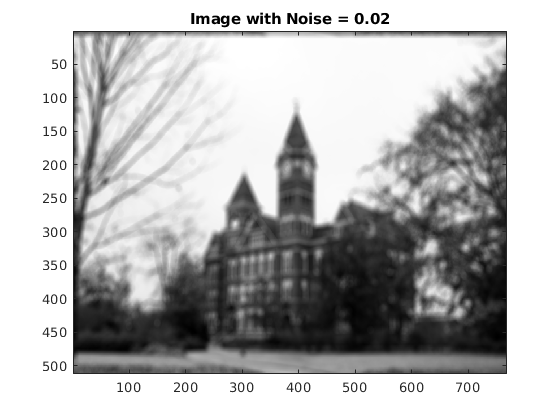


sigma = .02;
noise =  sigma * randn(size(image));
noise_image = blurred_image + noise;
figure(7)
imagesc(noise_image)
title(['Image with Noise = ', num2str(sigma)])

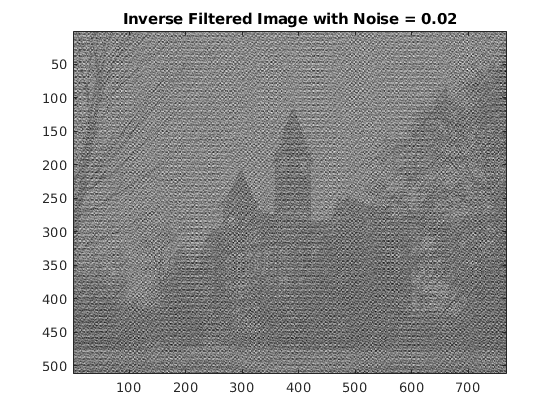


inverse_noise_image = real(...
    ifft2(...
    fft2(noise_image) ./ fft2(ker, size(blurred_image, 1), size(blurred_image, 2)))...
    );
figure(8)
imagesc(inverse_noise_image)
title(['Inverse Filtered Image with Noise = ', num2str(sigma)])

## Part 4: Regularized Inverse Filtering

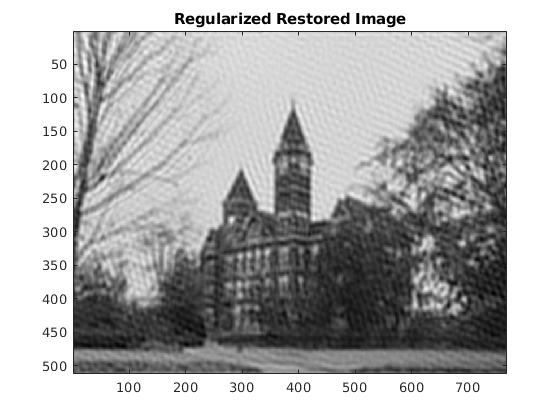

sigma = 5;
alpha = 0.2;
noise =  sigma * randn(size(image));
noise_image = blurred_image + noise;
noise_image_F = fft2(noise_image);

L = [0 1 0; 1 -4 1; 0 1 0];

% G: output (noisy, blurred image)
% D: blurring kernel
% F: input (original image)
% L: regularizing kernel
% alpha: regularizing scale factor

G = fft2(noise_image);
K_F = fft2(ker, size(image, 1), size(image, 2));
L_F = fft2(L, size(image, 1), size(image, 2));
F_hat = K_F ./ ( K_F.^2 + alpha * L_F.^2 ) .* G;
f_hat = real(ifft2(F_hat));

figure(9)
imagesc(f_hat);
title("Regularized Restored Image")